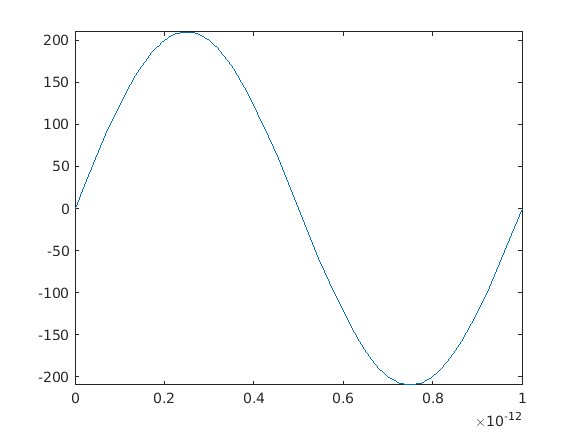

clear
format long %increasing number of decimals stored

%declaring variables
m = 9.1093837015*10^-31;
e = 1.602176634*10^-19;
dt = 1*10^-15;
T = 1*10^-12;
E0 = 210;

w = (2*pi)/T; 

syms E(t)
E(t) = E0*sin(w*t);

fplot(E, [0 1*10^-12])


%calculating E(0) as it varies
eval(E(0))

ans =      0


eval(E(dt))

ans =    1.319460232767379


eval(E(2*dt))

ans =    2.638868375504047


eval(E(3*dt))

ans =    3.958172340235717


eval(E(4*dt))

ans =    5.277320043100871



eval(E(499*dt))

ans =    1.319460232767417


eval(E(500*dt))

ans =      2.571758278209442e-14


eval(E(501*dt))

ans =   -1.319460232767458



eval(E(998*dt))

ans =   -2.638868375504122


eval(E(999*dt))

ans =   -1.319460232767349


eval(E(1000*dt))

ans =     -5.143516556418883e-14




%first iteration
eval((e*E(0)*dt)/m + 0)

ans =      0



%iteration 2
eval((e*E(dt)*dt)/m + ans)

ans =      2.320693060809364e-04



%iteration 3
eval((e*E(2*dt)*dt)/m + ans)

ans =      6.961987565439717e-04



%iteration 4
eval((e*E(3*dt)*dt)/m + ans)

ans =    0.001392370028353



%iteration 5
eval((e*E(4*dt)*dt)/m + ans)

ans =    0.002320555637859



%checking results
const = -e*E0*dt/m

const =   -0.036935220226215



%checking results
var=1000

var =         1000


const*sin(w*var*dt)

ans =      9.046519845167461e-18
